**Task 2.7**

We captured 9 images with different setup in the lab and used them to fit masks for segmentation.

(i) We choose color-space based color segmentation to benefit from the distinguishing features extracted by various color spaces (HSV and LAB). We dont use thresholding since it is too simple to work for distinguishing more than two colors. Moreover, k-means clustering, although an unsupervised complex algorithm, does not give control over the way it learns to distingusih colors. Since there are more background pixels in the image than foreground pixels, the xntroids formed would be noisy. Deicidng threshold to distinguish forground form background would result in loss of information. Moreover, it has the tendency to overfit on one image and poorly adapt to the noise of other images. 

We manually created color space based masked instead of using the ColorThresholder app since 

(i) it is easier to test and edit a manually made mask over multiple images and

(ii) We wanted to create a more accurate mask using features of multiple color spaces to benefit from both of them at teh same time (in teh case of blue mask).

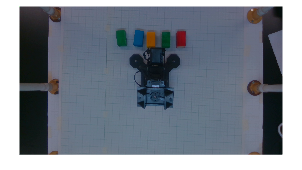

% Reading the image
img1 = imread("intro to rob\6_Color.png");
% filteredImage = imbilatfilt(img1, 1000, 50);
imshow(img1);

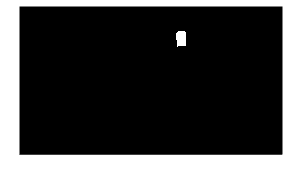


% we dont use rgb since r cannot distingusih between blue and green, g is
% identical everywhere and b blends in its background.

% Coverting rgb to LAB
img1lab = rgb2lab(img1);
[l a b] = imsplit(img1lab);

% Converting rgb to HSV
img1hsv = rgb2hsv(img1);
[h s v] = imsplit(img1hsv);

% Masking red block

% h extracts red color, and s extracts the color red where the saturation
% is high
redmask = h > 0.9 & s > 0.5 ;
imshow(redmask);

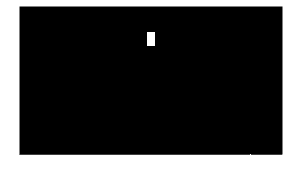


% Masking Yellow block

% h extracts color, s extracts regions of yellow with ihgh saturation and v
% ignores the dark yellow areas of the camera stand
yellowmask = s > 0.5 & h < 0.105 & v > 0.45;
imshow(yellowmask);

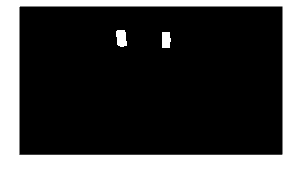


% Masking Green Block
% the a channel distinguished green from others distinctively
greenmask = a < -10;
imshow(greenmask);

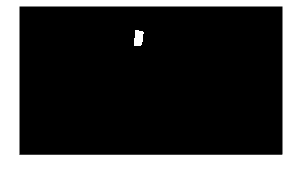


%Masking Blue Block

% uses feature extracted from lab and hsv
% b extracts blue color over yellow, v avoids blue areas with low
% brightness, l furtehr caters for some corner case of blue reflection on top of the robot
% arm
bluemask = b < -28 & v > 0.3 & l < 50;
imshow(bluemask);

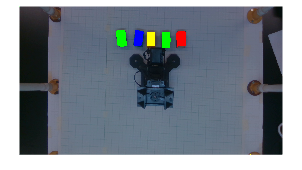


% Overlaying masks to view color segmentation

% Viewing the color segmentation
k1 = imoverlay(img1, redmask, "red");
k2 = imoverlay(k1, greenmask, "green");
k3 = imoverlay(k2, bluemask, "blue");
overlayimg = imoverlay(k3, yellowmask, "yellow");
imshow(overlayimg)

(iv) As evident, the masks work with a high success rate and distinguishes all colors in all 9 images in various locations. The masks are flexible enough to recognize colors in slight shadow conditions. In some cases, there are a few spots in between or undetected corners in the image. This is beacuse our masks are not adaptive and depedent on the ambient light. Therefore, a fair amount of change in light conditions can impact the performance of the segmentation masks.

Task 2.9

% a mask combining all the cubes (we just take all masks to identify each
% conncomp regardless of color for this task)

% masks come from task 2.7
allcubemask = redmask | greenmask | yellowmask | bluemask;
allcubemask = greenmask;

% remove the small non-cube noise masked pixels from amsk
allcubemask = bwpropfilt(allcubemask, "Area", [100 1080*1920]);
% find connected components
cubesCC = bwconncomp(allcubemask)

cubesCC = struct with fields:
    Connectivity: 8
       ImageSize: [1080 1920]
      NumObjects: 2
    PixelIdxList: {[7991×1 double]  [7229×1 double]}


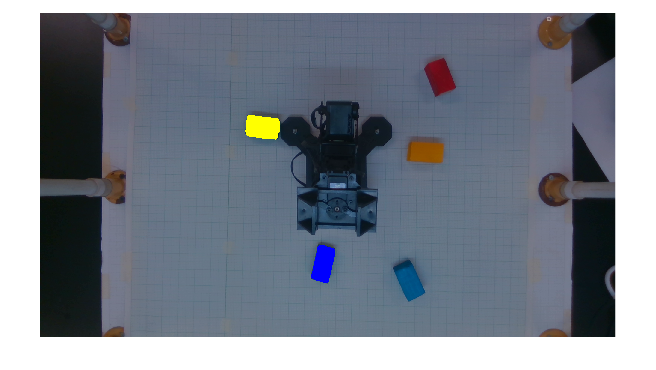


% label the cubes and show as rgb
cubelabel = label2rgb(bwlabel(allcubemask), "jet","k", "shuffle");
% imshow(cubelabel)
imshow(labeloverlay(img1, bwlabel(allcubemask), "Transparency", 0));

% create a watershed case and apply watershed
% test on more images